% Basis pursuit example

% Generate problem data

rand('seed', 0);
randn('seed', 0);

n = 3;
m = 1;
A = randn(m,n);

x = sprandn(n, 1, 0.1*n);
b = A*x;

xtrue = x;

[x history] = basis_pursuit(A, b, 1.0, 1.0);

iter	    r norm	   eps pri	    s norm	  eps dual	 objective
  1	    0.3091	    0.0033	    0.0000	    0.0033	      0.44
  2	    0.3091	    0.0033	    0.0000	    0.0064	      0.44
  3	    0.3091	    0.0033	    0.0000	    0.0094	      0.44
  4	    0.2362	    0.0033	    0.0871	    0.0118	      0.44
  5	    0.0743	    0.0034	    0.2242	    0.0122	      0.39
  6	    0.0771	    0.0042	    0.0820	    0.0118	      0.48
  7	    0.0518	    0.0040	    0.0137	    0.0115	      0.44
  8	    0.0060	    0.0037	    0.0248	    0.0115	      0.36
  9	    0.0090	    0.0036	    0.0082	    0.0115	      0.36
 10	    0.0055	    0.0037	    0.0019	    0.0116	      0.35
 11	    0.0004	    0.0037	    0.0027	    0.0116	      0.35
Elapsed time is 0.037196 seconds.


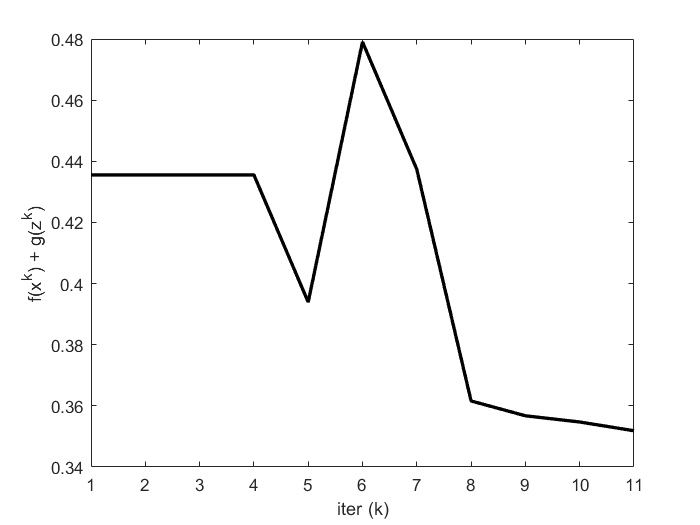


K = length(history.objval);

h = figure;
plot(1:K, history.objval, 'k', 'MarkerSize', 10, 'LineWidth', 2);
ylabel('f(x^k) + g(z^k)'); xlabel('iter (k)');

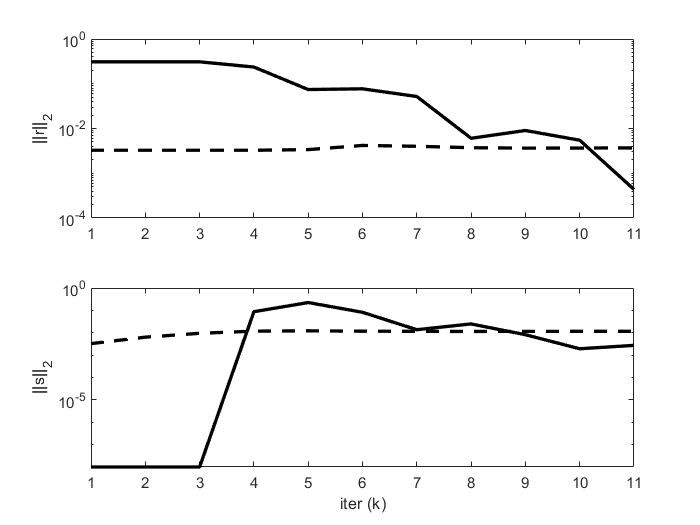


g = figure;
subplot(2,1,1);
semilogy(1:K, max(1e-8, history.r_norm), 'k', ...
    1:K, history.eps_pri, 'k--',  'LineWidth', 2);
ylabel('||r||_2');

subplot(2,1,2);
semilogy(1:K, max(1e-8, history.s_norm), 'k', ...
    1:K, history.eps_dual, 'k--', 'LineWidth', 2);
ylabel('||s||_2'); xlabel('iter (k)');

function [z, history] = basis_pursuit(A, b, rho, alpha)

t_start = tic;

QUIET    = 0;
MAX_ITER = 1000;
ABSTOL   = 1e-4;
RELTOL   = 1e-2;

[m n] = size(A);

x = zeros(n,1);
z = zeros(n,1);
u = zeros(n,1);

if ~QUIET
    fprintf('%3s\t%10s\t%10s\t%10s\t%10s\t%10s\n', 'iter', ...
      'r norm', 'eps pri', 's norm', 'eps dual', 'objective');
end

% precompute static variables for x-update (projection on to Ax=b)
AAt = A*A';
P = eye(n) - A' * (AAt \ A);
q = A' * (AAt \ b);

for k = 1:MAX_ITER
    % x-update
    x = P*(z - u) + q;

    % z-update with relaxation
    zold = z;
    x_hat = alpha*x + (1 - alpha)*zold;
    z = shrinkage(x_hat + u, 1/rho);

    u = u + (x_hat - z);

    % diagnostics, reporting, termination checks
    history.objval(k)  = objective(A, b, x);

    history.r_norm(k)  = norm(x - z);
    history.s_norm(k)  = norm(-rho*(z - zold));

    history.eps_pri(k) = sqrt(n)*ABSTOL + RELTOL*max(norm(x), norm(-z));
    history.eps_dual(k)= sqrt(n)*ABSTOL + RELTOL*norm(rho*u);

    if ~QUIET
        fprintf('%3d\t%10.4f\t%10.4f\t%10.4f\t%10.4f\t%10.2f\n', k, ...
            history.r_norm(k), history.eps_pri(k), ...
            history.s_norm(k), history.eps_dual(k), history.objval(k));
    end

    if (history.r_norm(k) < history.eps_pri(k) && ...
       history.s_norm(k) < history.eps_dual(k))
         break;
    end
end

if ~QUIET
    toc(t_start);
end

end

function obj = objective(A, b, x)
    obj = norm(x,1);
end

function y = shrinkage(a, kappa)
    y = max(0, a-kappa) - max(0, -a-kappa);
    
end
